clc
clear
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\camera_shake_detection\videos_Analysis\';
origin_filename='rescale_crop_fps10_DJI_0047_nonAvgIqtau_angle_Iqtau.mat';
input=[path origin_filename];
origin=load(input);
stable_filename='stabilized_rescale_crop_fps10_DJI_0047_nonAvgIqtau_angle_Iqtau.mat';
input=[path stable_filename];
stable=load(input);

angle_num=size(origin.angle_Iqtau,1);
qVec=1:size(origin.angle_Iqtau,2);
q_num=size(origin.angle_Iqtau,2);
tVec=1:size(origin.angle_Iqtau,3);
t_num=size(origin.angle_Iqtau,3);

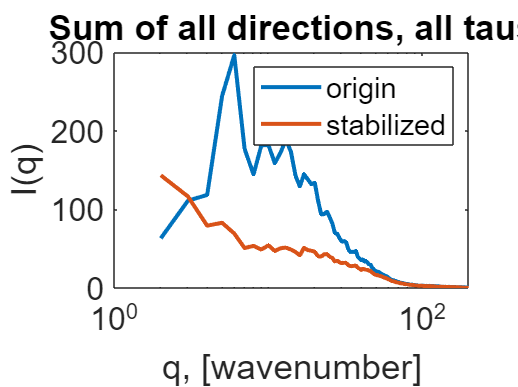

fig=figure();

q_max = 200;
q_start = 2;
y_origin=sum(sum(origin.angle_Iqtau(:,q_start:q_max,:),1),3);
y_stable=sum(sum(stable.angle_Iqtau(:,q_start:q_max,:),1),3);
semilogx(qVec(q_start:q_max),squeeze(y_origin),"LineWidth",2);
hold on
semilogx(qVec(q_start:q_max),squeeze(y_stable),"LineWidth",2);

legend('origin','stabilized')
% ylim([0 1.2*max(y)]);
%     xticks([0 0.001 0.01 0.1])
set(gca,'fontsize', 16); 
%     xlabel('q, [pixel^{-1}]')
xlabel('q, [wavenumber]')
ylabel('I(q)')

title('Sum of all directions, all taus')

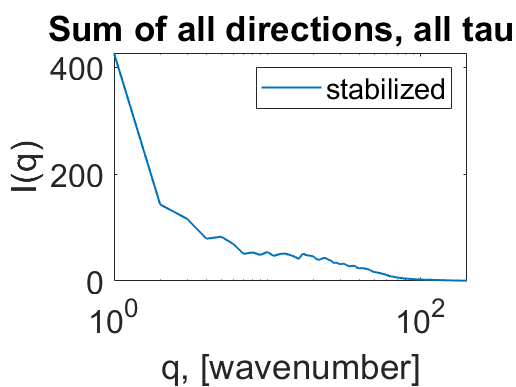

fig=figure();

q_max = 200;
y_origin=sum(sum(origin.angle_Iqtau(:,1:q_max,:),1),3);
y_stable=sum(sum(stable.angle_Iqtau(:,1:q_max,:),1),3);
% semilogx(qVec(1:q_max),squeeze(y_origin),"LineWidth",1);
% hold on
semilogx(qVec(1:q_max),squeeze(y_stable),"LineWidth",1);

legend('stabilized')
% ylim([0 1.2*max(y)]);
%     xticks([0 0.001 0.01 0.1])
set(gca,'fontsize', 16); 
%     xlabel('q, [pixel^{-1}]')
xlabel('q, [wavenumber]')
ylabel('I(q)')

title('Sum of all directions, all taus')

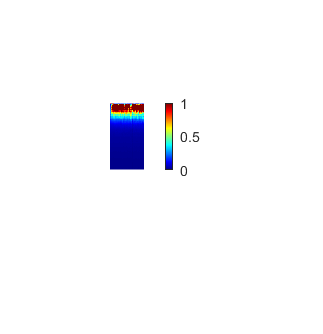

figure()
imshow(squeeze(sum(origin.angle_Iqtau(:,1:q_max,:),1)))
colormap('jet');
colorbar;

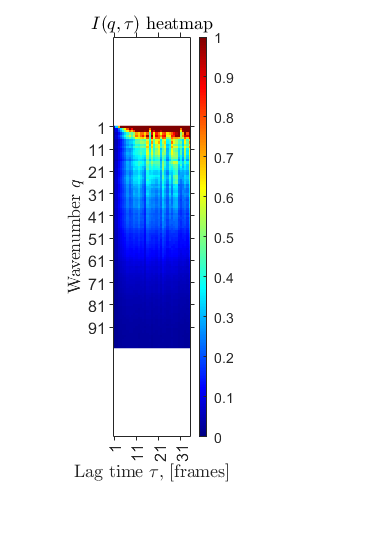

figure()
q_max = 100;
t_max = 35;
imshow(squeeze(sum(stable.angle_Iqtau(:,1:q_max,1:t_max),1)),'InitialMagnification', 400); % You can adjust the value as needed

colormap('jet');
colorbar;

% Set the aspect ratio of the axes to 'equal'


axis on;
% (Optional) Set custom ticks and labels
xticks(1:10:t_max);
yticks(1:10:q_max);

axis equal;
% % Set the axes to tight to remove extra white spaces
% axis tight;

% Add title and labels (optional)
title('$I(q,\tau)$ heatmap','Interpreter','latex');
xlabel('Lag time $\tau$, [frames]','Interpreter','latex')
ylabel('Wavenumber $q$','Interpreter','latex')

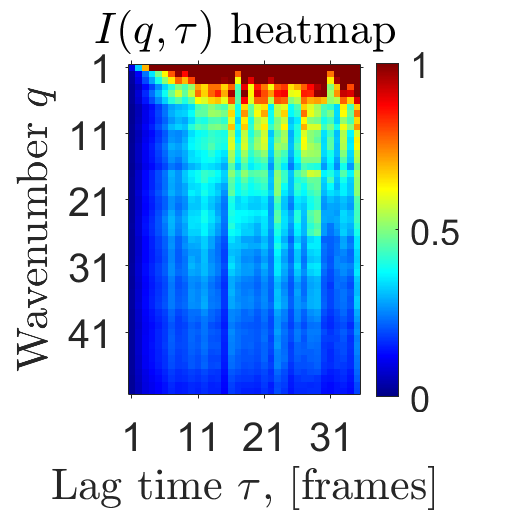

figure()
q_max = 50;
t_max = 35;
img = squeeze(sum(stable.angle_Iqtau(:,1:q_max,1:t_max),1)); % You can adjust the value as needed

% Create a square figure
fig = gcf;
fig.Position(3) = 500; % Set the width of the figure
fig.Position(4) = 500; % Set the height of the figure

% Calculate the aspect ratio
aspect_ratio = q_max / t_max;

% Display the image
ax = axes;
imshow(img, 'InitialMagnification', 'fit'); % Fit the image to the figure

% Adjust the aspect ratio of the axes
pbaspect(ax, [1 aspect_ratio 1]);

colormap('jet');
colorbar;

% Turn on the axis and set custom ticks and labels
axis on;
xticks(1:10:t_max);
yticks(1:10:q_max);

set(gca,'fontsize', 20); 
% Add title and labels (optional)
title('$I(q,\tau)$ heatmap','Interpreter','latex');
xlabel('Lag time $\tau$, [frames]','Interpreter','latex')
ylabel('Wavenumber $q$','Interpreter','latex')

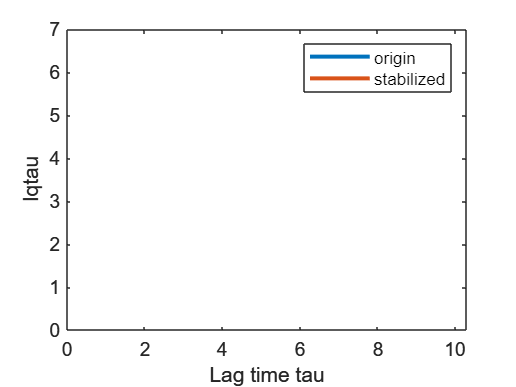

q = 6;
fps = 10;
x = tVec/fps;
z_origin = squeeze(sum(origin.angle_Iqtau(:,q,:),1));
z_stable = squeeze(sum(stable.angle_Iqtau(:,q,:),1));
figure()
plot(x,z_origin,'LineWidth',2)
hold on
plot(x(1:end-1),z_stable,'LineWidth',2)

legend('origin','stabilized')
xlabel('Lag time tau')
ylabel('Iqtau')

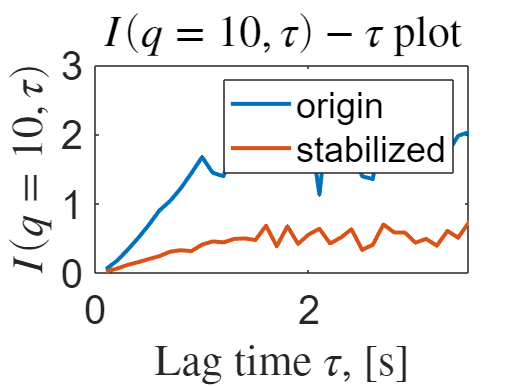

q = 10;
fps = 10;
x = tVec/fps;
z_origin = squeeze(sum(origin.angle_Iqtau(:,q,:),1));
z_stable = squeeze(sum(stable.angle_Iqtau(:,q,:),1));
figure()
plot(x,z_origin,'LineWidth',2)
hold on
plot(x(1:end-1),z_stable,'LineWidth',2)

xlim([0 3.5])

legend('origin','stabilized')
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')
title(['$I(q=$' int2str(q) '$,\tau)-\tau$ plot'],'Interpreter','latex')

scale=1024;
q_max=200;
tau = 9;
filename=[path 'rescale_crop_fps10_DJI_0047_nonAvgIqtau.mat']

filename = '\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\camera_shake_detection\videos_Analysis\rescale_crop_fps10_DJI_0047_nonAvgIqtau.mat'

origin_nonAvg=load(filename);
filename=[path 'stabilized_rescale_crop_fps10_DJI_0047_nonAvgIqtau.mat']

filename = '\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\camera_shake_detection\videos_Analysis\stabilized_rescale_crop_fps10_DJI_0047_nonAvgIqtau.mat'

stable_nonAvg=load(filename);
% imshow(fftshift(nonAvgIqtau(:,:,tau)));
% title(['Accumulate FFT diff of tau=' num2str(tau/framerate) 's'])
% filename = ['tau=' num2str(tau/framerate) 's.png'];
% saveas(gcf,[path filename])

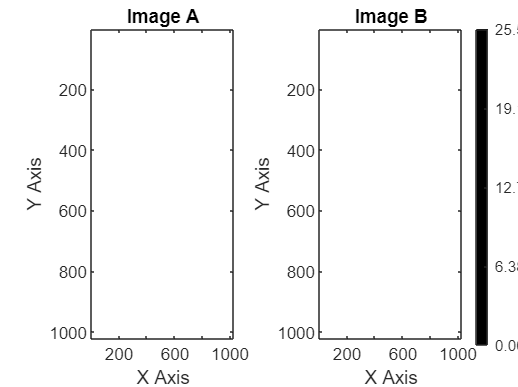

q_max = 100;
% Create two matrices (or load your images)
A = squeeze(origin_nonAvg.nonAvgIqtau(1:q_max,:,tau));
B = squeeze(stable_nonAvg.nonAvgIqtau(1:q_max,:,tau));

% Define the range of values for the colorbar
cmin = min([A(:); B(:)]);
cmax = max([A(:); B(:)]);

% Create a figure
figure;

% Display the first image
ax1 = subplot(1, 2, 1);
imagesc(A);
caxis([cmin, cmax]);
title('origin');
xlabel('X Axis');
ylabel('Y Axis');

% Display the second image
ax2 = subplot(1, 2, 2);
imagesc(B);
caxis([cmin, cmax]);
title('stable');
xlabel('X Axis');
ylabel('Y Axis');

% Add a shared colorbar
colormap(ax1, 'jet');
colormap(ax2, 'jet');
c = colorbar;
c.Position(1) = 0.92; % Adjust the position of the colorbar
c.Label.String = 'Color Scale';
c.Ticks = linspace(cmin, cmax, 5); % Set the tick values for the colorbar

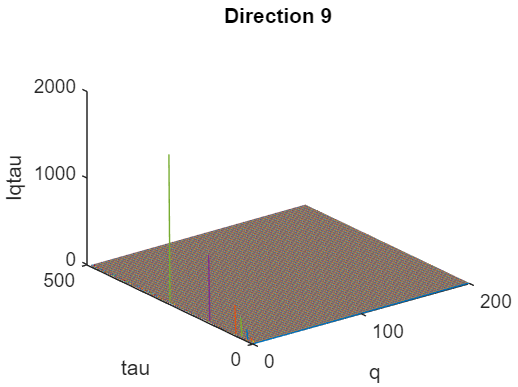

q_max=200;
figure()
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(angle_Iqtau(5,(1:q_max),:)))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Direction 9')

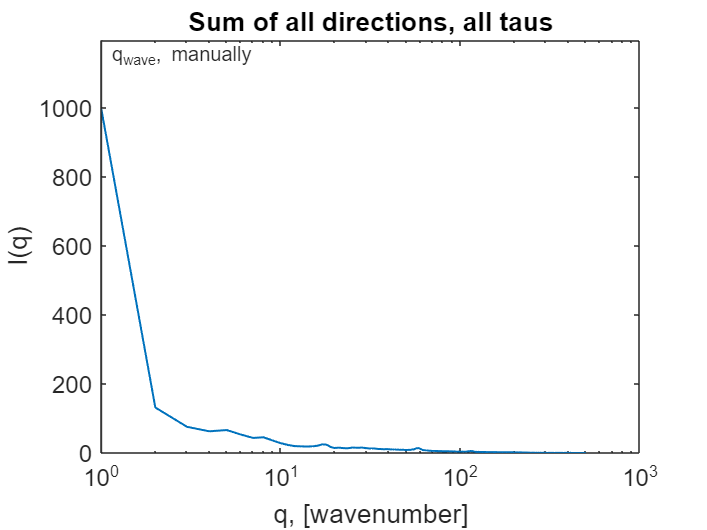

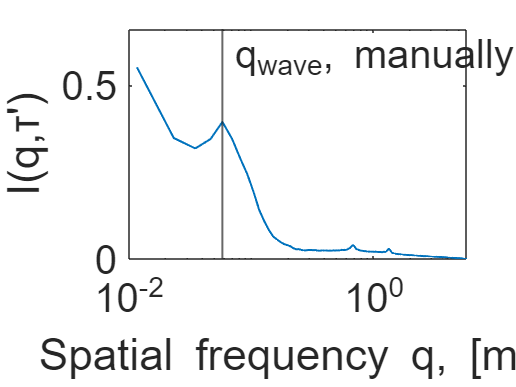

q = 8;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
% plot(x,y,'o','LineWidth',2)


exclude=x>1.5;

% y = A*(1-exp(cos(2*pi*v*x))).*exp(x/tau_c)+B;
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, 'StartPoint', [0.05, 0.3, -1, 1], 'Exclude', exclude)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =      0.1323  (0.1173, 0.1473)
       B =      0.1828  (0.1768, 0.1888)
       tau_c =     -0.7679  (-0.9223, -0.6134)
       v =      0.8965  (0.8651, 0.9279)

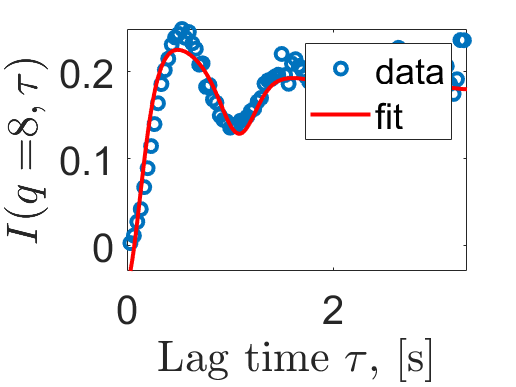

h=plot( f, x, y ,"o") ;
h(1).LineWidth=2;
h(2).LineWidth=2;

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

q = 60;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
% plot(x,y,'o','LineWidth',2)


exclude=x>1.5;

% y = A*(1-exp(cos(2*pi*v*x))).*exp(x/tau_c)+B;

ft = fittype('fit_function(x,A,v,tau_c,B)');
tau_c_fixed = -0.7679;
v_fixed = 0.8965;
lower_bounds = [ -Inf -Inf tau_c_fixed-0.5 v_fixed ];
upper_bounds = [ Inf Inf tau_c_fixed v_fixed ];
fit_options = fitoptions('Method', 'NonlinearLeastSquares',...
                         'Lower', lower_bounds,...
                         'Upper', upper_bounds,...
                         'StartPoint', [0.05, 0.3, -1, 1],...
                         'Exclude', exclude);
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, fit_options)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =     0.01746  (0.006153, 0.02876)
       B =     0.04344  (0.03819, 0.04869)
       tau_c =     -0.7679  (fixed at bound)
       v =      0.8965  (fixed at bound)

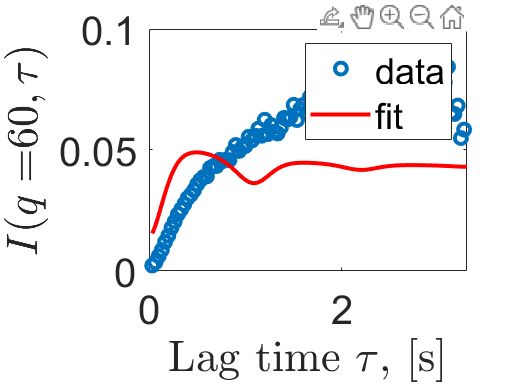

h=plot( f, x, y ,"o") ;
h(1).LineWidth=2;
h(2).LineWidth=2;

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

q = 5;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
% plot(x,y,'o','LineWidth',2)


exclude=x>1.5;

% y = A*(1-exp(cos(2*pi*v*x))).*exp(x/tau_c)+B;

ft = fittype('fit_function(x,A,v,tau_c,B)');
tau_c_fixed = -0.7679;
v_fixed = 0.8965;
lower_bounds = [ -Inf -Inf tau_c_fixed-0.5 v_fixed ];
upper_bounds = [ Inf Inf tau_c_fixed v_fixed ];
fit_options = fitoptions('Method', 'NonlinearLeastSquares',...
                         'Lower', lower_bounds,...
                         'Upper', upper_bounds,...
                         'StartPoint', [0.05, 0.3, -1, 1],...
                         'Exclude', exclude);
% StartPoint order: A,B,tau_c,v
f = fit( x(:), y, ft, fit_options)

f =      General model:
     f(x) = fit_function(x,A,v,tau_c,B)
     Coefficients (with 95% confidence bounds):
       A =      0.2157  (0.179, 0.2523)
       B =      0.3216  (0.3046, 0.3386)
       tau_c =     -0.7679  (fixed at bound)
       v =      0.8965  (fixed at bound)

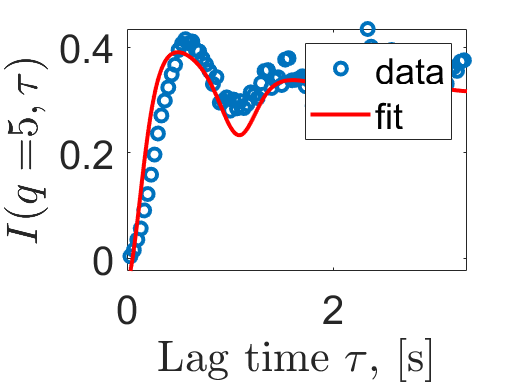

h=plot( f, x, y ,"o") ;
h(1).LineWidth=2;
h(2).LineWidth=2;

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

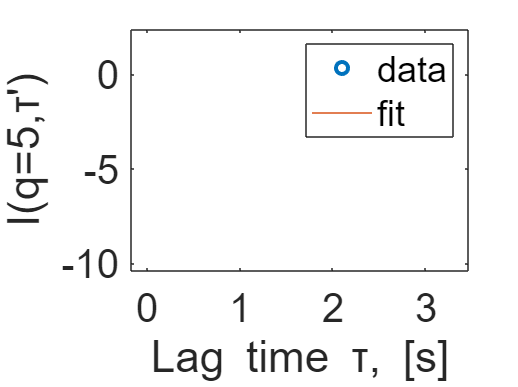

q = 5;
x = tVec/10;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
plot(x,y,'o','LineWidth',2)
hold on
% StartPoint order: A,B,tau_c,v
A = 5.20;
B = 0.33;
tau_c = -0.5;
v = 1;
x_th = 0:0.01:3.3;
y_th = A*(1-exp(cos(2*pi*v*x_th))).*exp(x_th/tau_c)+B;
plot(x_th, y_th) 

legend('data','fit')
xlim([0 3.3]);
set(gca,'fontsize', 20); 
xlabel('Lag time \tau, [s]','Interpreter','tex')
ylabel(['I(q=' int2str(q) ',\tau'')'],'Interpreter','tex')

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\real_videos_exp\water_closeup_cropped_Analysis\';
filename='19V_2023-02-22-132638-0000_nonAvgIqtau.mat';
input=[path filename];
theta=0;
wavenumber=3;
scale=1024;
q_range=10;
tau=3;
plotFFTdifference(input,theta,wavenumber,scale,q_range,tau,path)

tau=3;
scale=1024;
wavenumber=3;
q_max=q_num;
plotIq_all_dirc_selected_tau(angle_Iqtau,tau,path,wavenumber,scale,q_max)

clf
t=10;
q_max=100;
for i=1:angle_num/4
    y=sum(angle_Iqtau(i:i+3,1:q_max,t));
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
clf
t=10;
q_max=100;
for i=1:angle_num
    y=angle_Iqtau(i,1:q_max,t);
    plot(qVec(1:q_max),y)
    hold on
end
legend
xlabel('q')
ylabel('Iqtau')
title('Iqtau-q in different directions')

figure()
y=squeeze(sum(sum(angle_Iqtau(:,3:end,:),2),3));
bar(1:angle_num,y);
xticks(1:angle_num)
ylim([0 1.2*max(y)])
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title('Sum of Iqtau in 16 directions')
set(gca,'fontsize', 16);

figure()
% q=3;
q=3;
y=squeeze(sum(sum(angle_Iqtau(:,q,:),2),3));
bar(1:angle_num,y);
xticks(1:angle_num)
ylim([0 1.2*max(y)])
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau in 16 directions for q=' num2str(q)])
set(gca,'fontsize', 16);

figure()
q_max=20;
imagesc(squeeze(sum(angle_Iqtau(:,1:q_max,:),1)));
xticks([50 100 150])
xticklabels({'5','10','15'})
xlabel('lag time tau(s)')
ylabel('wavenumber q')
title('I(q,tau) heatmap')
colorbar;
set(gca,'fontsize', 12);

figure()
q=2;
plot(tVec/10,squeeze(sum(angle_Iqtau(:,q,:),1)),'-o')
% ylim([0 0.02])
xlim([0 3])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
title(['I(q=' num2str(q) ',tau)-tau plot'])
set(gca,'fontsize', 12);

q=3;
x=tVec(:)/10;
y=squeeze(sum(angle_Iqtau(:,q,:),1));
% exclude=[1 2];
% FT = fittype('x./210000 + k.*x.^n')
ft = fittype( 'fit_function(x,A,v,tau_c,B)' );
% StartPoint order: A,B,tau_c,v
f = fit( x, y, ft, 'StartPoint', [10, 10, 1000, 2])
h=plot( f, x, y ,"o"); 
h(1).LineWidth=2;
h(2).LineWidth=2;
xlim([0 3])
ylim([0 10])
title(['I(q=' num2str(q) ',tau)-tau plot'])
xlabel('lag time tau(s)')
ylabel(['I(q=' num2str(q) ',tau)'])
legend('data','fit')
set(gca,'fontsize', 16);

q=3;
figure();
bar(1:angle_num,squeeze(sum(angle_Iqtau(:,q,:),3)));
xticks(1:angle_num)
xlabel('direction *pi/16')
ylabel('sum of Iqtau')
title(['Sum of Iqtau(q=' num2str(q) ') in 16 directions'])

% x_label=(0:angle_num-1)*180/angle_num
% strsplit(num2str(round(x_label)))
% set(gca,'xticklabel',{'40 feet','60 feet','120 feet'})

figure()
bar(1:angle_num,squeeze(sum(sum(angle_Iqtau,2),3)));

figure()
plot(1:t_num,squeeze(angle_Iqtau(1,1,:)))

imagesc(log(squeeze(sum(angle_Iqtau(5,1:10,:),1))))

q_max=50;
figure()
z=sum(angle_Iqtau(1:16,(1:q_max),:),1);
plot3(repmat((qVec(1:q_max))',1,t_num),repmat((tVec),q_max,1),squeeze(z))
% xlim([0 200])
xlabel('q')
ylabel('tau')
zlabel('Iqtau')
title('Sum of all directions')

num_of_wave_on_diagonal=1.41;
scale=1024;
q_max=200;
plotIq(filename,path,num_of_wave_on_diagonal,scale,q_max)
